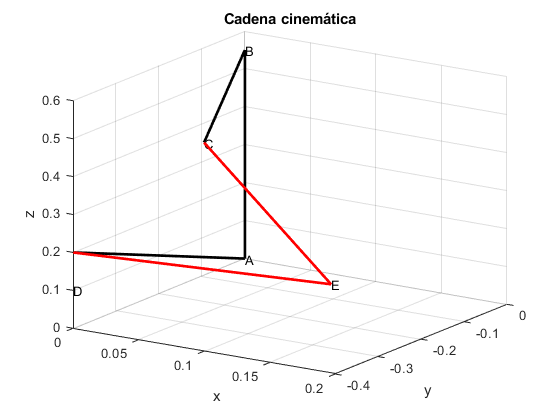

clear 
clc

theta_C=0;
beta=0;
P_z=0.55;
Z_arfada=0;
C_x=0.1;
C_y=-0.4;
D_x=0;
D_y=-0.4;
D_z=0.2;
A=[0;0;0];
B=[0;0;P_z+Z_arfada];
C=[C_x,C_y,0];
D=[D_x;D_y;D_z];
L_m=0.2;
theta1=pi/18;


Ci=PosCi(C,theta_C,beta);
DA=A-D;
AB=B-A;
Ci=Ci(1:3,4);
Ci=Ci+B;


vABx=linspace(A(1),B(1),100);
vABy=linspace(A(2),B(2),100);
vABz=linspace(A(3),B(3),100);

vDAx=linspace(A(1),D(1),100);
vDAy=linspace(A(2),D(2),100);
vDAz=linspace(A(3),D(3),100);

vBCx=linspace(B(1),Ci(1),100);
vBCy=linspace(B(2),Ci(2),100);
vBCz=linspace(B(3),Ci(3),100);


Ei=D+(L_m.*[cos(theta1); 0; sin(theta1)]);


vDEx=linspace(D(1),Ei(1),100);
vDEy=linspace(D(2),Ei(2),100);
vDEz=linspace(D(3),Ei(3),100);

vECx=linspace(Ei(1),Ci(1),100);
vECy=linspace(Ei(2),Ci(2),100);
vECz=linspace(Ei(3),Ci(3),100);

plot3(vABx,vABy,vABz,'k',"LineWidth",2)
hold on
plot3(vDAx,vDAy,vDAz,'k',"LineWidth",2)
plot3(vBCx,vBCy,vBCz,'k',"LineWidth",2)
plot3(vDEx,vDEy,vDEz,'r',"LineWidth",2)
plot3(vECx,vECy,vECz,'r',"LineWidth",2)

text(D(1),D(2),D(3)-0.1,'D')
text(Ei(1),Ei(2),Ei(3),'E')
text(0,0,0,'A')
text(B(1),B(2),B(3),'B')
text(Ci(1),Ci(2),Ci(3),'C')
hold off
xlabel("x")
ylabel("y")
zlabel("z")
grid on
title("Cadena cinemática")

%DEi=(L_m.*[cos(theta1); 0; sin(theta1)]);
%EiCi=L_b*[sin(theta3)*cos(theta1+theta2);cos(theta3);sin(theta3)*sin(theta1+theta2)];


function [Pf] = PosCi(Pi,theta,beta) 
Pf=[1 0 0 0;0 cos(beta) -sin(beta) 0; 0 sin(beta) cos(beta) 0; 0 0 0 1]*[cos(theta) 0 sin(theta) 0;0 1 0 0; -sin(theta) 0 cos(theta) 0;0 0 0 1]*[1 0 0 Pi(1);0 1 0 Pi(2);0 0 1 Pi(3);0 0 0 1];
end